# Test Best Models -  Decision Tree & K-Nearest Neighbor

## Setup

clear; clc; % Clear workspace
rng(1) % set seed for reproducability

% Load test data
test = readtable('test.csv', 'ReadVariableNames', true);
feature_names = test.Properties.VariableNames(2:end); % save feature names for plot

test = test{:,:};  % Convert to matrix

X_test = test(:, 2:end);
y_test = test(:, 1);

% Load models
load('dt_best.mat', 'dt_best')
load('knn_best.mat', 'knn_best')

## Test Models (CV = k-fold, loss = accuracy, SMOTE)

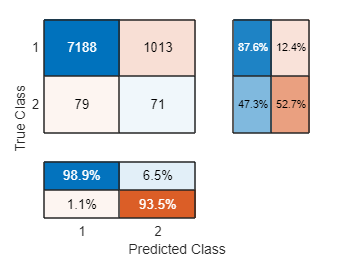

accuracy = 0.8692

precision = 0.0655

recall = 0.4733

specificity = 0.8765

fb = 0.2108

% 6a) Test Decision Tree on test data
test_model(dt_best, X_test, y_test)

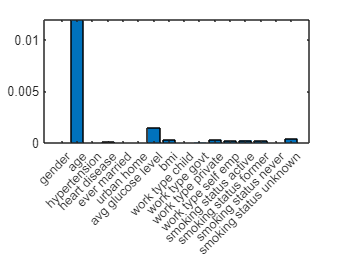


% Plot feature importance
imp = predictorImportance(dt_best);
bar(imp)
set(gca, 'XTick', 1:length(feature_names),'XTickLabel',strrep(feature_names,'_',' '))

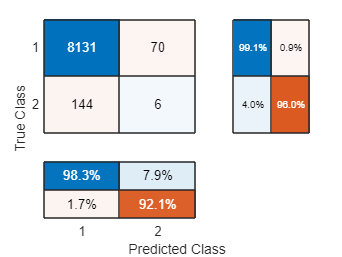

accuracy = 0.9744

precision = 0.0789

recall = 0.0400

specificity = 0.9915

fb = 0.0444

% 6b) Test KNN on test data
test_model(knn_best, X_test, y_test)

## Helper Functions

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);  % Predict with test data
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    cm = confusionchart(cmat);  % Plot confusion matrix
    cm.RowSummary = 'row-normalized';  % Add row summary
    cm.ColumnSummary = 'column-normalized';  % Add column summary
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) % Calculate metrics
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);  % Get confusion matrix
    tn = cmat(1,1);  % True negative
    fn = cmat(2,1);  % False negative
    tp = cmat(2,2);  % True positive
    fp = cmat(1,2);  % False positive

    % Statistics of interest for confusion matrix
    b = 2; % beta < 1 favors precision. beta > 1 favors recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp); % accuracy
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2*fn + fp); % F-beta score (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 